# Advanced Topics in Control

  Exercise - Poleplacement and LQR

Institute for Electrical Engineering in Medicine

  Georg Männel

  28/06/2019

## Load Model Parameters

clear variables

iPendelModelParameters

## Initial values for the simulation

 theta0 =  pi/2; %% Initial pendulum angle [rad]
dtheta0 = -pi/2; %% Initial pendulum angular velocity [rad/s]
  dphi0 =  1000; %% Initial motor speed [rad/s]

u_dist    = 500e-3; %% Disturbance

## Change the system in order to use the first two states

A_s = A(1:2,1:2);
B_s = B(1:2);
C_s = C(1,1:2);
D_s = 0;
G_s = ss(A_s,B_s,C_s,D_s);

## 1a) -c) Controller design with pole placement

Determination of the region in the imaginary plane, in which the poles can be placed to fullfill the requirement. For a Second Order System,the transferfunction is given as follows: 

 
$$G\left(s\right)=\frac{\omega_n }{s^2 +2\frac{\zeta }{\omega_n }s+{\omega_{n\text{ }} }^{2\text{ }} \text{ }}$$


- $\zeta$ = damping factor 

- $\omega_n$ = natural frequency 

The connection between the control goals and the parameters in the transfer-function are given by:

- rise time: $t_r =\frac{1,8}{\omega_n }$

- maximal overshoot: $M_p =\mathrm{exp}\left(\frac{-\pi \zeta }{\sqrt{1-\zeta^{2\text{ }} }}\right)$

-  settling time $t_s =\frac{4,6\text{ }}{\text{ }\zeta \text{ }\omega_n }=\frac{4,6}{|\sigma |\text{ }}$

this can be used to calculate bounds for the parameters


omega_n_min = 1.8/0.5; % rise time below 0.5 seconds 
zeta_min = abs(log(0.05))/sqrt((log(0.05))^2 + pi^2); % Overshoot below 5%
sigma_max = 4.6/2; % settling time below 2 seconds; It is a maximum, because the poles are required to be in the left half plane


Let the pole pair of the second order system be denoted by $\sigma +i\omega_d$, then the following holds:


$$\sigma =\omega_n \zeta$$


$\mathrm{sin}\left(\theta \right)=\frac{\sigma }{\omega_n }$, $\theta$ is the angle between imaginary-axis and the line going through origin and pole.


$$\omega_d =\omega_n \sqrt{1-\zeta^{2\text{ }} }$$


this can be used to define an aray in which the poles must lie to fulfill the given requirements

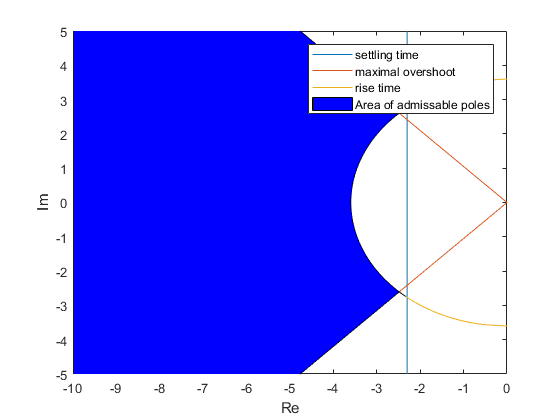


plot_area_for_admissiable_poles(0.5,0.05,2)

The poles of the closed loop system are allowd to lay inside the blue highlighted area in order to fullfil the given requirements.Within this area the poles can be placed arbitrally, for example:


poles = [-11.5827 + 0.5106i, -11.5827 - 0.5106i];


For placing the selected poles, the state feedback gain $\mathrm{K}$ has to be calculated accordingly. Therefore the eigenvalues of the closed loop system matrix $A-\mathrm{BK}\text{ }$are calculated to be equal to the selcted poles. Thus for the given system this is achieved by solving

$\begin{array}{l}
\mathrm{det}\left(p_1 \mathrm{I}-\left(A-\mathrm{BK}\right)\right)=0\\
\mathrm{det}\left(p_2 \mathrm{I}-\left(A-\mathrm{BK}\right)\right)=0\text{ }
\end{array}$ (1)

for $k_1$ and $k_{2\text{ }}$ the vector elemts of $\mathrm{K}$.


K_place = place(A_s,B_s,poles); % Solves (1) for K


The calculated controller is integrated in the Simulink Model iPendelumML_PolePlacement.slx in the subsystem Controller.

 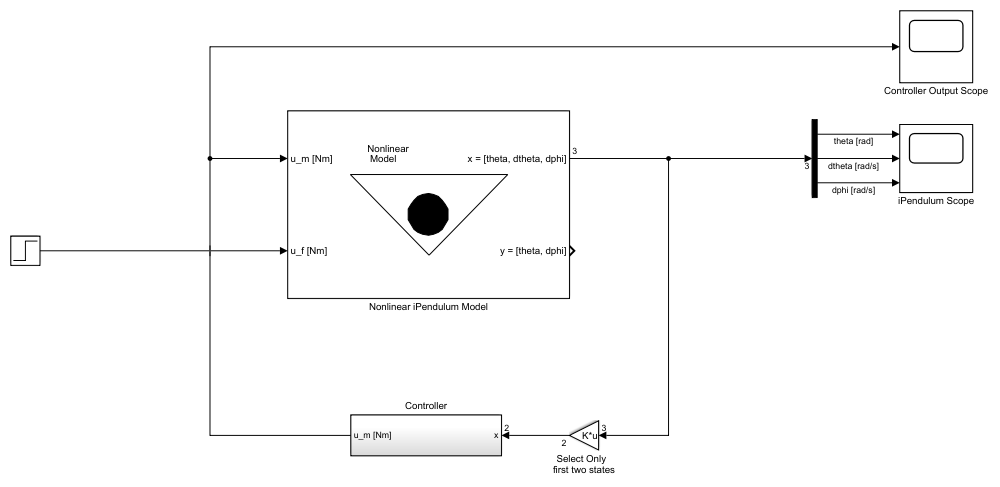

Within this simulation the system lays initially flat on one of its sides while the motor rotates with 1000 rpm. The controller will steer the system into upright position, until after 5s an input disturbance brings the system out of equilibrium and the controller acts accordingly.

How does the system behavior change, during the transission to upright position and when the disturbance strikes, when you move the closed loop poles deeper into the left half plane?

How does the system behavior change, during the transission to upright position and when the disturbance strikes,  when you increase the imaginary part of the poles?

## 1d) Output feedback 

For controlling the system only by using the outputs, it is required to design an observer and include it into the controll system such as:

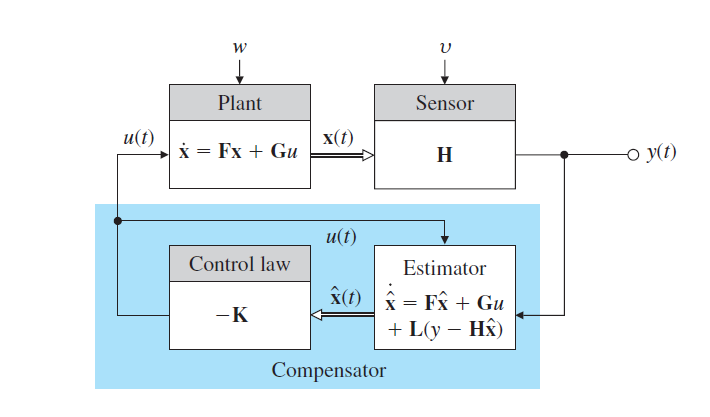

This can be achieved by using a Lueneberger Observer, given by the structure:

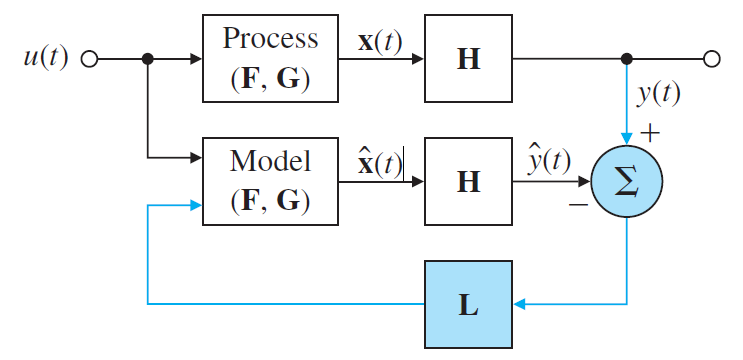

For the fixed observer gain the obsever state dynamic and the error dynamic is described by:

$\dot{\hat{x} } =\mathrm{F}\hat{x} \text{ }+\text{ }\mathrm{Gu}+L\left(y-\mathrm{H}\hat{x} \right)$,

$\varepsilon^{˙} =\dot{x} -\dot{\hat{x} } =\left(\mathrm{F}-\mathrm{LH}\right)\varepsilon$.

Since the observer design is dual to the controller design, we once again can use pole placement to design the observer. The poles should be chosen to converge faster than the controller, otherwise they can be chosen arbitrary. 


p_obs = [-100.0; -30 ];


When placing the poles, once again place() can be used. By doing so dimensions have to be considered


L_place = place(A_s',C_s',p_obs)';


The calculated controller is integrated in the Simulink Model iPendulumML_Observer.slx in the subsystem observer.

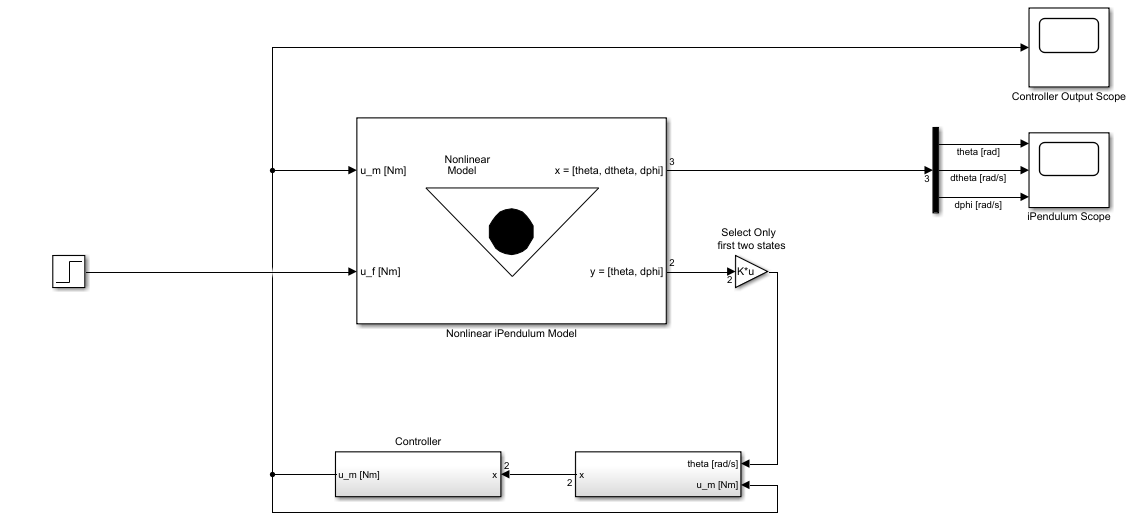

## 2) Reference Tracking 

In order to achieve reference tracking for the angle the controller shall be extended. The simplest way to achieve this is to by introducing a feedforward controller defining the steady state for the system.

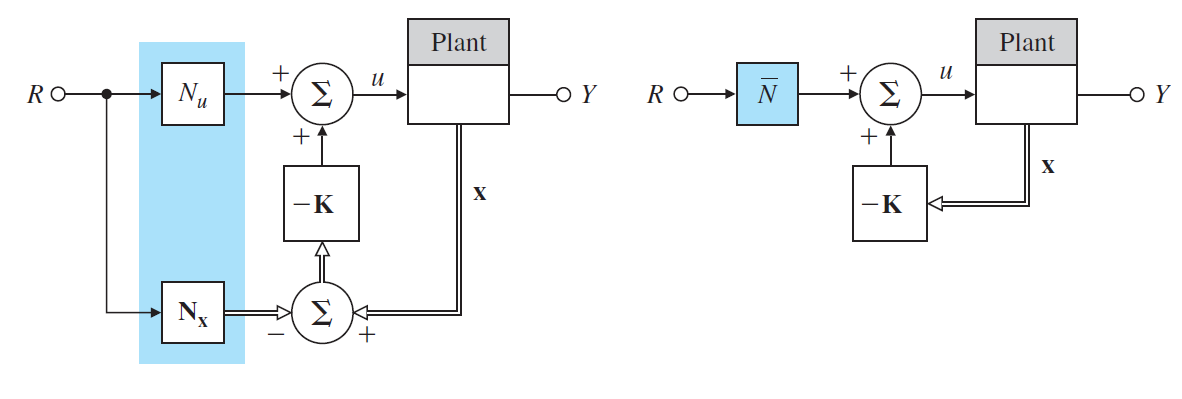

The feedforward gains can be calulated by solving:


$$\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & B\\
C & D
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
N_x \\
N_u 
\end{array}\right\rbrack$$


The single input solution can be calculated using block diagramm algebra, and is given by:


$$\overline{N} =N_u +{\mathrm{KN}}_{x\text{ }}$$



% Define the reference angle
r_theta    = 15/180*pi; 

% construct the matrix describing the whole system, with full state feedback
M_sys = [A_s, B_s; C_s, 0];

% construct reference vector
r = [0 0 1]';

% calculated steady state paramteres
N = M_sys\r;
N_x = N(1:2);
N_u = N(3);

% calculated single feedforward controller
N_bar = N_u+K_place*N_x;


Both version of the feedforward controller are implemented in iPendulumML_Refernce.slx

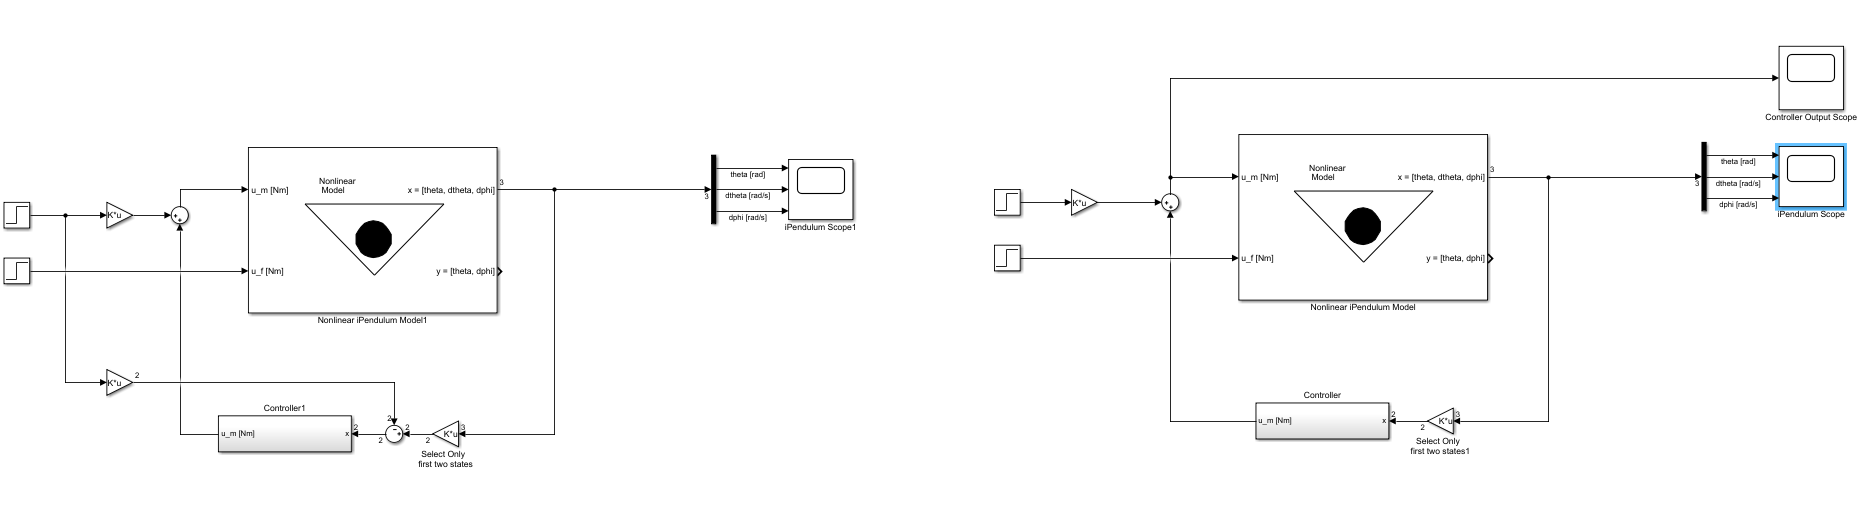

What might be the benefit of implementing the reference method with two feedforward gains instead of one?

Why is the system not capable of following the disturbance once the disturbance kicks in after 5s?

Why is it actually not possible to stabilize the system in an arbitrary angle? (Hint: what happens with the motorspeed?)

In order to achieve reference tracking, even in presence of the disturbance, the controller shall be changed to implement the integrator method. Therfore the integral of the error is used as an extra state resulting the augmented statespace model:


$$\left\lbrack \begin{array}{c}
\dot{X} \\
\mathrm{E}
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & A\\
0 & C
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X\\
\int E
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\\
D
\end{array}\right\rbrack u-\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack r$$


% State Augmentation 
A_aug = [A_s [0;0]; C_s 0];
B_aug = [B_s ; 0];


The controller of the system can once again be designed using pole placement, or any other statespace technique. The resulting block diagramm is:

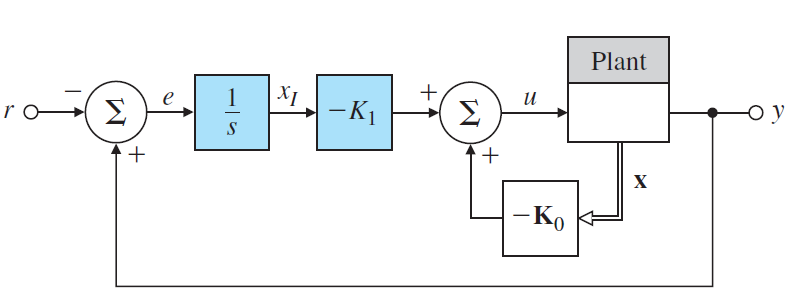


% place extra pol
p_aug = [poles, -10];

% calculated controller gains
K_aug = place(A_aug,B_aug,p_aug);


The controller with the augmented state feedback is implemented in iPendulumML_Reference_Augmentation.slx.

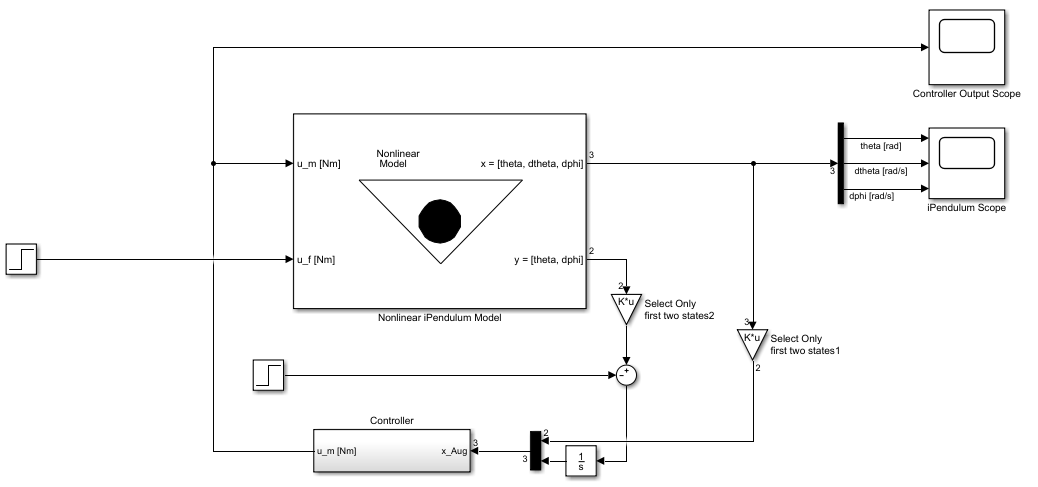

How does the system behaviour change when the extra pole is moved in the complex plain?

Where should the third pole at least be placed, in order to use the techniques from one to achive the desired controller performance?

## 3) Controller Design with Optimal Control

Instead of the using pole placement to calculate the controller gains, a linear quadratic regulated (LQR) shall be designed.


% Construct the weighting matrices
Q_lqr = diag([1 1]);
R_lqr = 500;

% calculate the state feedback gain
K_lqr = lqr(A_s,B_s,Q_lqr,R_lqr,[]);


The controller is implemented in the Simulink model iPendulumML_Lqr.slx

How does a change in the weights of the controller effect the controlleffort und state transition?

How does a change in the weights effect the poles of the closed loop system?